# CS3200 Introduction to Scientific Computing

## Assignment #6 - due April 18 

Author: Robert Li    

Uid:  u1212360

## Problem 1: **QR Factorization, EigenValues & comparing solutions to Ax=b**:

(a) Perform a QR decomposition on this matrix using the [MATLAB qr(A) function](https://www.mathworks.com/help/matlab/ref/qr.html).  Plot the A, Q and R matrix using the spy function on a 1x3 subplot.  What do you notice about the shape of Q and R?

clear all, close all, clc, clf
% Your solution for pt a 
A = [0.7577 0.7060 0.8235 0.4378 2.7260;
    0.7431 0.0318 0.6948 0.3816 1.8514;
    0.3922 0.2769 0.3171 0.7655 1.7518;
    0.6555 0.0462 0.9502 0.7952 2.4471;
    0.1712 0.0971 0.0344 0.1869 0.4896];

b = [1;1;1;1;1];
[Q,R] = qr(A);

subplot(3,1,1);
spy(Q);

subplot(3,1,2);
spy(R);

subplot(3,1,3);
spy(A);


(b) Use the code provided in lecture to calculate the eigenvalues of A and compare the values to the values given by the [MATLAB function eig(A).](https://www.mathworks.com/help/matlab/ref/eig.html)

% Your solution for pt b 
A = [0.7577 0.7060 0.8235 0.4378 2.7260;
    0.7431 0.0318 0.6948 0.3816 1.8514;
    0.3922 0.2769 0.3171 0.7655 1.7518;
    0.6555 0.0462 0.9502 0.7952 2.4471;
    0.1712 0.0971 0.0344 0.1869 0.4896];

Asave = A;
for i = 1:15
    [Q,R] = qr(A);
    A = R*Q;
end
A

A =     2.7442   -1.7148   -0.0957   -1.6663   -3.5144
   -0.0000   -0.4853    0.0015    0.1522    0.0784
    0.0000    0.0282    0.4177    0.2971   -0.1339
   -0.0000   -0.0002   -0.0033   -0.2852    0.0551
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000


bans = eig(Asave)

bans =     2.7442
    0.4164
   -0.4853
   -0.2838
   -0.0000


(c) Solve Ax=b using [MATLAB’s mldivide function](https://www.mathworks.com/help/matlab/ref/mldivide.html) (x=A\b).

% Your solution for pt c 
A = [0.7577 0.7060 0.8235 0.4378 2.7260;
    0.7431 0.0318 0.6948 0.3816 1.8514;
    0.3922 0.2769 0.3171 0.7655 1.7518;
    0.6555 0.0462 0.9502 0.7952 2.4471;
    0.1712 0.0971 0.0344 0.1869 0.4896];
b = [1;1;1;1;1];

cans = mldivide(A,b)

cans = 	1.0e+04 *

    1.2127
    1.2141
    1.2128
    1.2120
   -1.2125


(d) Solve Ax=b using the normal equations

% Your solution for pt d
A = [0.7577 0.7060 0.8235 0.4378 2.7260;
    0.7431 0.0318 0.6948 0.3816 1.8514;
    0.3922 0.2769 0.3171 0.7655 1.7518;
    0.6555 0.0462 0.9502 0.7952 2.4471;
    0.1712 0.0971 0.0344 0.1869 0.4896];
b = [1;1;1;1;1];
AT = transpose(A);

dans=(AT*A)^-1*AT*b

dans = 	1.0e+04 *

    1.2127
    1.2141
    1.2128
    1.2120
   -1.2125


(e) Solve Ax=b using QR decomposition 

% Your solution for pt e
A = [0.7577 0.7060 0.8235 0.4378 2.7260;
    0.7431 0.0318 0.6948 0.3816 1.8514;
    0.3922 0.2769 0.3171 0.7655 1.7518;
    0.6555 0.0462 0.9502 0.7952 2.4471;
    0.1712 0.0971 0.0344 0.1869 0.4896];

b = [1;1;1;1;1];
[Q,R] = qr(A);

eans = R\Q'*b

eans = 	1.0e+04 *

    1.2127
    1.2141
    1.2128
    1.2120
   -1.2125


(f) Compare the accuracy of the three above solutions (c and d)  by calculating the 2-norms of Ax-b for each solution.

% Your solution for pt f
A = [0.7577 0.7060 0.8235 0.4378 2.7260;
    0.7431 0.0318 0.6948 0.3816 1.8514;
    0.3922 0.2769 0.3171 0.7655 1.7518;
    0.6555 0.0462 0.9502 0.7952 2.4471;
    0.1712 0.0971 0.0344 0.1869 0.4896];

b = [1;1;1;1;1];
[Q,R] = qr(A);

x1 = mldivide(A,b);
x2 = (AT*A)^-1*AT*b;
x3 = R\Q'*b;
cData = norm(b-A*x1,2)

cData = 6.3012e-12

dData = norm(b-A*x2,2)

dData = 1.2541e-06

eData = norm(b-A*x3,2)

eData = 8.9575e-12

Method used: Simply applied all the equation on the slide from lecture for all the questions.

(a) A has same shape as Q. The factor `R` is an `m`-by-`n` upper-triangular matrix, and the factor `Q` is an `m`-by-`m` orthogonal matrix. Therefore, an `m`-by-`m` orthogonal matrix times an `m`-by-`n` upper-triangular matrix equal to an `m`-by-`m` orthogonal matrix.

## Problem 2: Solving the Least Squares Problem using QR Decomposition:

(a) Plot the temperature data

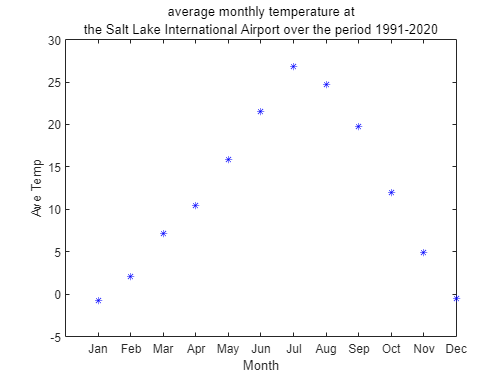

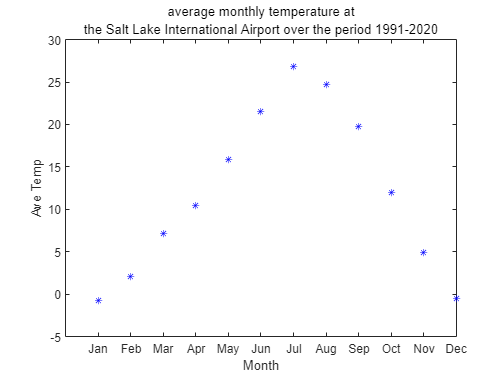

clear all, close all, clc, clf
% Your solution for pt a

aveTemp=[-0.8 2.1 7.2 10.5 15.9 21.5 26.8 24.7 19.8 12 4.9 -0.5];
month = 1:12;
 figure, plot(aveTemp,'b*')
 set(gca,'xtick',month,...
 'xticklabel',{'Jan','Feb','Mar','Apr','May','Jun','Jul','Aug','Sep','Oct','Nov','Dec'})
title('average monthly temperature at', 'the Salt Lake International Airport over the period 1991-2020')
xlabel('Month') 
ylabel('Ave Temp') 

(b) Use QR decomposition to calculate the line of best fit, the quadratic of best fit, the cubic of best fit and the quartic of best fit.  Use a 2x2 subplot to show the different lines of fit.

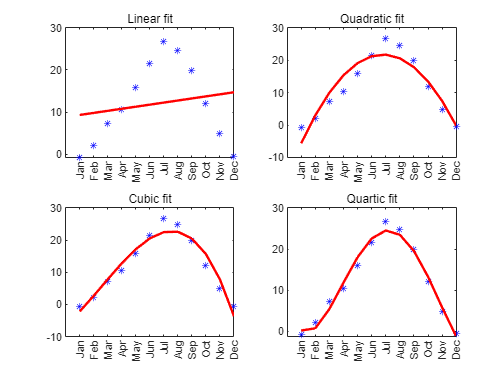

% Your solution for pt b
y = aveTemp';
x = month';

hL = [ones(length(y), 1),x];
hQuad = [ones(length(y), 1),x,x.^2];
hC = [ones(length(y), 1),x,x.^2,x.^3];
hQuar = [ones(length(y), 1),x,x.^2,x.^3,x.^4];

[Q,R] = qr(hL);
[Q1,R1] = qr(hQuad);
[Q2,R2] = qr(hC);
[Q3,R3] = qr(hQuar);

Astar = R\Q'*y;
Astar1 = R1\Q1'*y;
Astar2 = R2\Q2'*y;
Astar3 = R3\Q3'*y;

yTilde = hL*Astar;
yTilde1 = hQuad*Astar1;
yTilde2 = hC*Astar2;
yTilde3 = hQuar*Astar3;

%%%
subplot(2,2,1)
 plot(aveTemp,'b*');
 set(gca,'xtick',month,...
 'xticklabel',{'Jan','Feb','Mar','Apr','May','Jun','Jul','Aug','Sep','Oct','Nov','Dec'});
 grid on
 hold on
plot(x, yTilde,'r-','LineWidth',2);
title('Linear fit')
grid off
hold off
%%%

%%%
subplot(2,2,2)
 plot(aveTemp,'b*');
 set(gca,'xtick',month,...
 'xticklabel',{'Jan','Feb','Mar','Apr','May','Jun','Jul','Aug','Sep','Oct','Nov','Dec'});
 grid on
 hold on
plot(x, yTilde1,'r-','LineWidth',2);
title('Quadratic fit')
grid off
hold off
%%%

%%%
subplot(2,2,3)
 plot(aveTemp,'b*')
 set(gca,'xtick',month,...
 'xticklabel',{'Jan','Feb','Mar','Apr','May','Jun','Jul','Aug','Sep','Oct','Nov','Dec'});
 grid on
 hold on
plot(x, yTilde2,'r-','LineWidth',2);
title('Cubic fit')
grid off
hold off
%%%

%%%
subplot(2,2,4)
 plot(aveTemp,'b*')
 set(gca,'xtick',month,...
 'xticklabel',{'Jan','Feb','Mar','Apr','May','Jun','Jul','Aug','Sep','Oct','Nov','Dec'});
 grid on
 hold on
plot(x, yTilde3,'r-','LineWidth',2);
title('Quartic fit')
grid off
hold off

%%%

(c) Calculate the 2-norm of the residual to determine the best fit.

% Your solution for pt c
res1 = norm(y - yTilde,2)

res1 = 31.7178

res2 = norm(y - yTilde1,2)

res2 = 11.0048

res3 = norm(y - yTilde2,2)

res3 = 8.0794

res4 = norm(y - yTilde3,2)

res4 = 4.8208

Method used: Applied the method from discussion video, and applied qr decomposition for modified function.

## Problem 3: **Using SVD with the Hilbert Equations**:

(a) Create a Hilbert matrix of dimension 15.  Calculate b using ***b=Hx*** setting all entries of x=1, so that you have an exact solution to compare with.  Solve this system using ***x_solve=H\b ***and report the norm 2 error, ie ***dx = *****||*****x-x_solve*****||** 

clear all, close all, clc, clf
% Your solution for pt a
for n = 1:15
    H = hilb(n);
end
x = [1;1;1;1;1;1;1;1;1;1;1;1;1;1;1];
b = H*x;
x_solve = H\b;

dx = norm(x-x_solve,2)

dx = 23.7834

(b) Calculate the SVD of the Hilbert matrix and plot H, S, V, D using the spy function.  What do you observe?

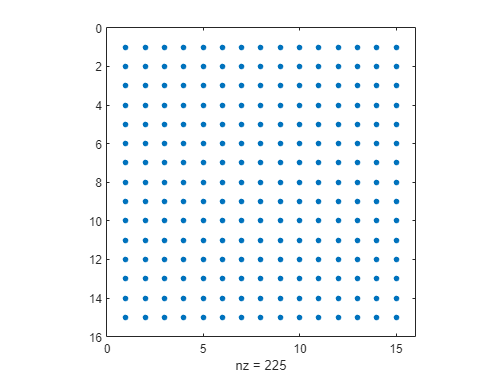

% Your solution for pt b
[U,S,V] = svd(H);
spy(U);

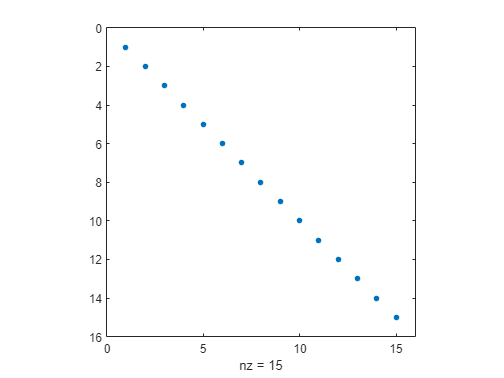

spy(S);

spy(V);

(c) Construct the matrix pseudo-inverse from the SVD and then use it to solve for x to obtain **x_svd**.  Compare the norm 2 error with your solution from (a) Is this more accurate?

% Your solution for pt c
Sinv = S';
for i=1:15
    Sinv(i,i) = 1.0/S(i,i);
end
Hinv = V * Sinv * U';

x_svd = Hinv\b;

norm(b-x_svd)

ans = 4.6468

(d) Now filter the S matrix in the following way. If a diagonal element of S is less than a tolerance, set it to zero and the corresponding diagonal entry in inv(S) to zero. Use the following values of tol=[1e-10, 1e-12, 1e-14, 1e-16] and make a table of the accuracy of the solutions.  Compare this accuracy with the solution you found in part (a).

% Your solution for pt d
tol=[1e-10, 1e-12, 1e-14, 1e-16];
norm2 = zeros(4,1);

for j = 1:4
S_diagonal = diag(S);
invS_DiagonalS = diag(inv(S));
for i = 1:length(S)
if S_diagonal(i)<tol(j)
S_diagonal(i) = 0;
invS_DiagonalS(i) = 0;
end
end
A = U*diag(S_diagonal)*V; 
x = A\b;
norm2(j) = norm(b-x);
end

table(tol',norm2)

ans = 4×2 table
    Var1       norm2   
    _____    __________

    1e-10    9.7039e+05
    1e-12        4951.9
    1e-14        940.95
    1e-16        68.443


Method used: Followed the requirement from questions, and the slide's function.

(b) From my observation, the Hilbert matrix has 255 non-zero entries , with only 15 singular values. Which make U and V's entries be the same.

(c) Yes, it is more accurate.

(d)1e -10 has best accuracy.

## Problem 4: **SVD for Image Compression**:

a) Take a selfie and import it into MATLAB, convert to greyscale and calculate the SVD, then plot the diagonal values of the S matrix.

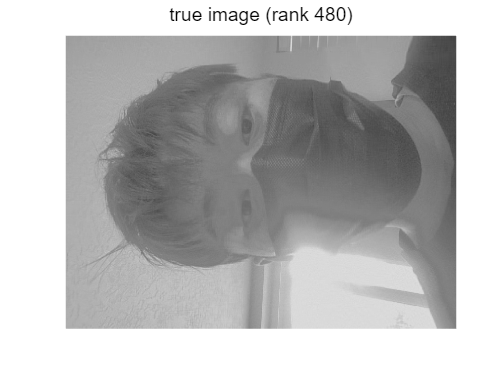

clear all, close all, clc, clf
% Your solution for pt a
load selfie.jpg

A = imread('selfie.jpg');
X = double(rgb2gray(A));

[U,S,V] =svd(X);
figure(1),clf

image(X), colormap(gray)
axis equal, axis off
 
title('true image (rank 480)','fontsize',16)

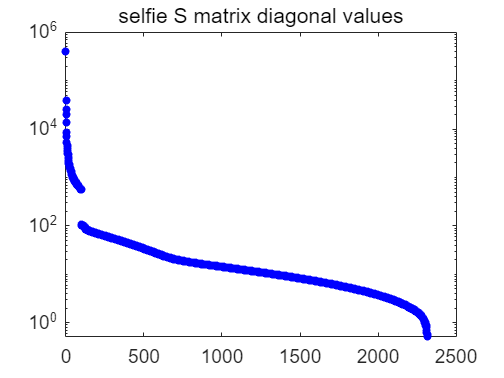


figure(2),clf
semilogy(diag(S),'b.','markersize',20)
set(gca,'fontsize',16)
title('selfie S matrix diagonal values')

(b) Create a matrix of the same size and fill with random numbers, to create a random greyscale image.  Calculate the SVD of the random image.

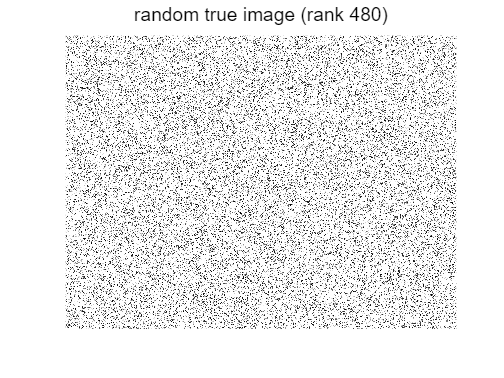

% Your solution for pt b
M = randi([0 1000],2316,3088);

[U,S1,V] = svd(M);
 
% "gatlin" stores the image as the variable "X"
figure(1),clf
% plot the original image
image(M), colormap(gray)
% image: MATLAB command to display a matrix as image
axis equal, axis off
 
title('random true image (rank 480)','fontsize',16)

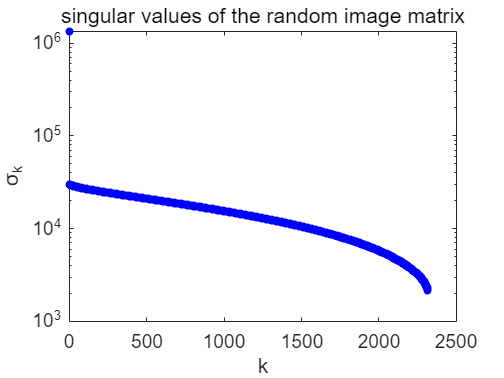

figure(2),clf

semilogy(diag(S1),'b.','markersize',20)
set(gca,'fontsize',16)
title('singular values of the random image matrix')
xlabel('k'), ylabel('\sigma_k')

(c) Create a 2x2 subplot and create two plots for each of the above images (your image and the random image).  Plot one should be a semilog plot of the diagonal values of S and the second plot should be the cumulative sum of the diagonal values divided by the sum of the diagonal values (Hint: plot(cumsum(diag(S1))/sum(diag(S1))) Set your xlim to view the left size of the images (I used the setting xlim([0 1550]).  Compare your two plots and explain what they mean.

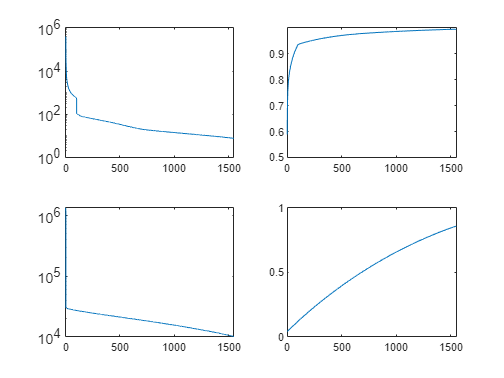

% Your solution for pt c
subplot(2,2,1);
semilogy(diag(S));
xlim([0 1550]);
subplot(2,2,2);
plot(cumsum(diag(S))/sum(diag(S)));
xlim([0 1550])
subplot(2,2,3);
semilogy(diag(S1));
xlim([0 1550])
subplot(2,2,4);
plot(cumsum(diag(S1))/sum(diag(S1)));
xlim([0 1550])

(d) Create a 2x2 subplot with 4 images, the original greyscale image and images with rank 5, 20, 100.

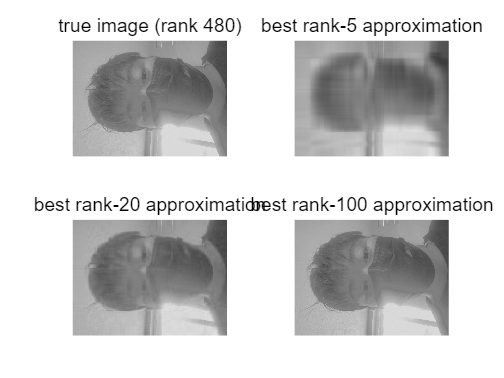

% Your solution for pt d
load selfie.jpg

A = imread('selfie.jpg');
X = double(rgb2gray(A));

[U,S,V] = svd(X);
figure(2),clf
% plot the original image
subplot(2,2,1),image(X), colormap(gray)
% image: MATLAB command to display a matrix as image
axis equal, axis off
 
title('true image (rank 480)','fontsize',16)
k_values = [5 20 100]; % Image ranks 
for i = 1 : length(k_values)
    k = k_values(i); 
    
    Xk = U(:,1:k)*S(1:k,1:k)*V(:,1:k)';

    subplot(2,2,i+1)
    image(Xk), colormap(gray)
    axis equal, axis off
    title(sprintf('best rank-%d approximation',k),'fontsize',16)    
end

(c)random picture has more smooth slope, I assume it because the svd in there has better rules.

## Extra Credit: SVD for compression on color image

Return to the original color image and use the provided MATLAB code for color images to experiment with different levels of compression to see how much you can compress the image while retaining a reasonable representation.  Make an estimate of how much space can be saved using the compressed representation.

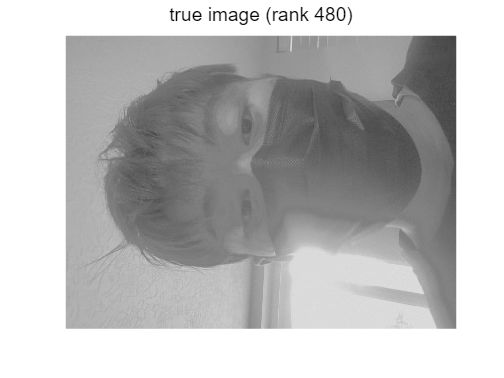

% Solution to extra credit 
clear all; 
close all; 
hold on; 

load selfie.jpg

A = imread('selfie.jpg');
X = double(rgb2gray(A));
% load the "gatlin" image data, built-in to MATLAB

[U,S,V] = svd(X);
 
% "gatlin" stores the image as the variable "X"

figure(1),clf
 % plot the singular values

figure(2),clf

% plot the original image 

image(X), colormap(gray)

% image: MATLAB command to display a matrix as image

axis equal, axis off
 
title('true image (rank 480)','fontsize',16)

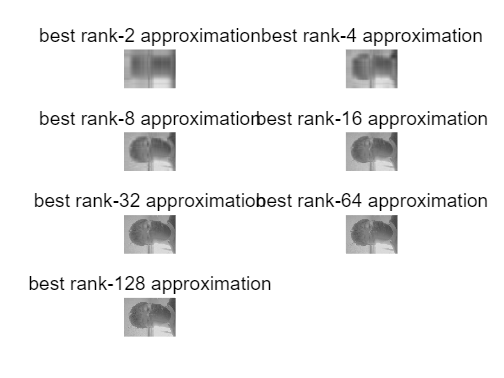


figure(3),clf
 
% plot the rank-k approximation

k_values = [2 4 8 16 32 64 128]; % Image ranks 
j=1;
for i = 1 : length(k_values)
    k = k_values(i); 
    
    Xk = U(:,1:k)*S(1:k,1:k)*V(:,1:k)';

    subplot(4,2,j)
    image(Xk), colormap(gray)
    axis equal, axis off
    title(sprintf('best rank-%d approximation',k),'fontsize',16)
        
    imwrite(Xk, gray, sprintf('selfie.jpg', k)); 
    j = j + 1;
end

The SVD definitely reduce the file size. It depends on how context of how the image used.

The file size:

rank 2:4KB

rank 4: 6KB

rank 8: 8 KB

rank 16: 13KB

rank 32:23KB

rank 64: 37KB

rank 128: 44KB